## Load Data and Initial plot

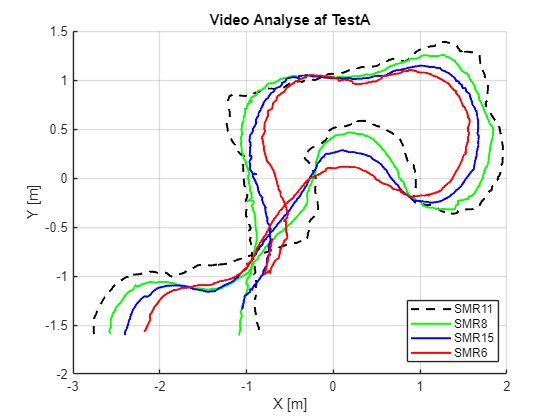

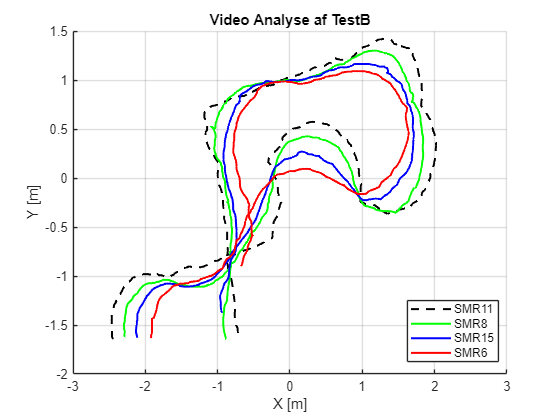

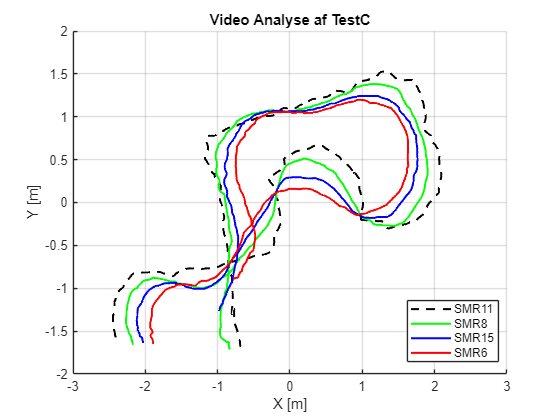

clc; clear; close all;

% --- Configuration ---
base_path = 'C:\Users\Markus\Desktop\Video af Test';
tests = {'Test A', 'Test B', 'Test C'};
robot_names = {'SMR11', 'SMR8', 'SMR15', 'SMR6'};  % Order matches X, X2, X3, X4

% --- Color & Style maps for plotting ---
color_map = containers.Map({'SMR6','SMR8','SMR15','SMR11'}, {'r','g','b','k'});
style_map = containers.Map({'SMR6','SMR8','SMR15','SMR11'}, {'-','-','-','--'});

% --- Storage struct ---
AllTests = struct();

% --- Load and process each test ---
for t = 1:length(tests)
    test_name = tests{t};
    folder = fullfile(base_path, test_name);
    csv_file = fullfile(folder, [test_name, '.csv']);
    test_field = matlab.lang.makeValidName(test_name);  % e.g., Test_A

    if ~isfile(csv_file)
        warning('⚠️ Missing file: %s', csv_file);
        continue;
    end

    % --- Read table with preserved variable names ---
    opts = detectImportOptions(csv_file, 'VariableNamingRule', 'preserve');
    data = readtable(csv_file, opts);
    AllTests.(test_field).raw = data;

    % --- Auto-match columns using order (X, X2, X3, X4, etc.) ---
    col_names = data.Properties.VariableNames;
    x_cols = find(contains(col_names, 'X'));
    y_cols = find(contains(col_names, 'Y'));
    n_robots = min(length(x_cols), length(y_cols));

    % --- Extract each robot trajectory ---
    for r = 1:n_robots
        robot = robot_names{r};
        x_col = col_names{x_cols(r)};
        y_col = col_names{y_cols(r)};

        % Read column data
        x = data.(x_col);
        y = data.(y_col);

        % Fix comma decimal strings if needed
        if iscell(x)
            x = strrep(x, ',', '.');
            x = str2double(x);
        end
        if iscell(y)
            y = strrep(y, ',', '.');
            y = str2double(y);
        end

        % Filter out NaN
        valid = ~(isnan(x) | isnan(y));
        x = x(valid);
        y = y(valid);

        AllTests.(test_field).(robot).x = x;
        AllTests.(test_field).(robot).y = y;
    end
end

% --- Plot each test ---
fields = fieldnames(AllTests);
for t = 1:length(fields)
    test = fields{t};
    figure;
    hold on;
    title(['Video Analyse af ', test], 'FontWeight', 'bold');
    xlabel('X [m]');
    ylabel('Y [m]');
    grid on;

    for r = 1:length(robot_names)
        robot = robot_names{r};

        if isfield(AllTests.(test), robot)
            x = AllTests.(test).(robot).x;
            y = AllTests.(test).(robot).y;

            plot(x, y, ...
                'Color', color_map(robot), ...
                'LineStyle', style_map(robot), ...
                'LineWidth', 1.5, ...
                'DisplayName', robot);
        end
    end

    legend('Location', 'best');
end

## Global Coordinate Swap

% --- Skew correction based on lower-left corner angles ---
theta_map = containers.Map( ...
    {'TestA', 'TestB', 'TestC'}, ...
    [90.12, 90.35, 87.58]);  % Degrees

test_names = fieldnames(AllTests);

for i = 1:length(test_names)
    test = test_names{i};

    % Only proceed if angle is defined
    if ~isKey(theta_map, test)
        warning('⚠️ No angle defined for %s, skipping.', test);
        continue;
    end

    % --- Define skew transformation ---
    theta_deg = theta_map(test);
    theta_rad = deg2rad(theta_deg);
    S = [1, cos(theta_rad); 0, sin(theta_rad)];  % 2x2 skew matrix

    % --- Loop over robots ---
    robots = fieldnames(AllTests.(test));
    for r = 1:length(robots)
        robot = robots{r};

        % Skip only individual robots with missing fields
        if ~isfield(AllTests.(test).(robot), 'x') || ~isfield(AllTests.(test).(robot), 'y')
            warning('⚠️ Skipping %s in %s due to missing fields.', robot, test);
            continue;
        end

        % Apply transformation
        x_s = AllTests.(test).(robot).x;
        y_s = AllTests.(test).(robot).y;
        P_skewed = [x_s(:)'; y_s(:)'];
        P_global = S * P_skewed;

        % Store globally transformed coordinates
        AllTests.(test).(robot).xg = P_global(1, :)';
        AllTests.(test).(robot).yg = P_global(2, :)';
    end
end

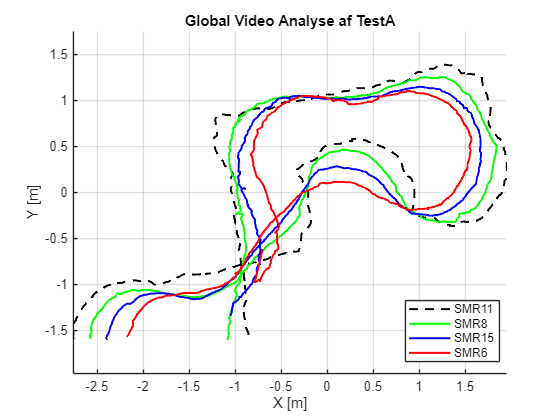

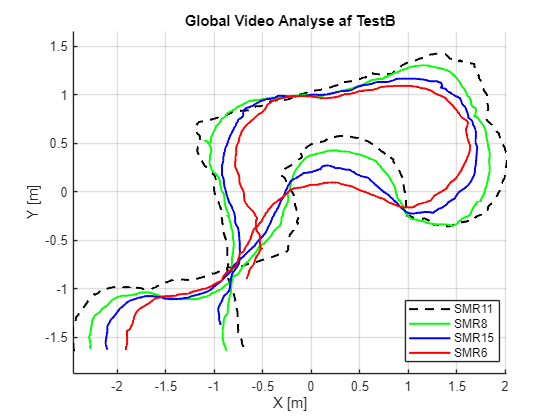

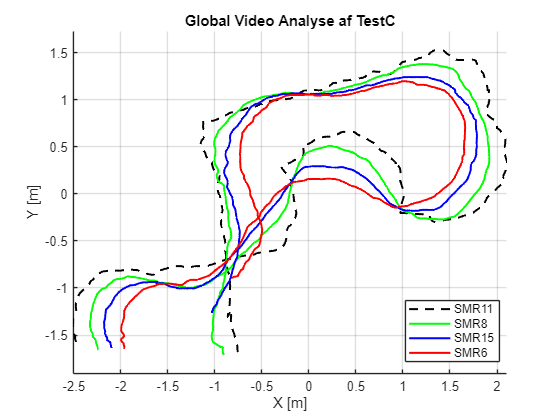


% --- Plot each test using global coordinates ---
fields = fieldnames(AllTests);
for t = 1:length(fields)
    test = fields{t};
    figure;
    hold on;
    title(['Global Video Analyse af ', test], 'FontWeight', 'bold');
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal;
    grid on;

    for r = 1:length(robot_names)
        robot = robot_names{r};

        % Only plot if transformed coordinates exist
        if isfield(AllTests.(test), robot) && ...
           isfield(AllTests.(test).(robot), 'xg') && ...
           isfield(AllTests.(test).(robot), 'yg')

            xg = AllTests.(test).(robot).xg;
            yg = AllTests.(test).(robot).yg;

            plot(xg, yg, ...
                'Color', color_map(robot), ...
                'LineStyle', style_map(robot), ...
                'LineWidth', 1.5, ...
                'DisplayName', robot);
        end
    end

    legend('Location', 'best');
end



% --- Configuration ---
reference = 'SMR11';
followers = {'SMR6', 'SMR8', 'SMR15'};

% --- Initialize result table ---
stats = table('Size', [0 9], ...
    'VariableTypes', {'string', 'string', 'double', 'double', 'double', 'double', 'double', 'double', 'double'}, ...
    'VariableNames', {'Test', 'Robot', 'MeanErr', 'StdErr', 'MinErr', 'MaxErr', 'MedianErr', 'Q1', 'Q3'});

% --- Loop over tests ---
test_names = fieldnames(AllTests);
for t = 1:length(test_names)
    test = test_names{t};

    if ~isfield(AllTests.(test), reference)
        warning('Skipping %s: no SMR11 data.', test);
        continue;
    end

    % --- Get SMR11 global trajectory ---
    x_ref = AllTests.(test).(reference).xg;
    y_ref = AllTests.(test).(reference).yg;

    % --- Loop over follower robots ---
    for r = 1:length(followers)
        robot = followers{r};

        if ~isfield(AllTests.(test), robot) || ...
           ~isfield(AllTests.(test).(robot), 'xg') || ...
           ~isfield(AllTests.(test).(robot), 'yg')
            warning('Skipping %s in %s: missing global coordinates.', robot, test);
            continue;
        end

        x_f = AllTests.(test).(robot).xg;
        y_f = AllTests.(test).(robot).yg;

        % --- Interpolate to common time base ---
        t_common = linspace(0, 1, 500);
        x_ref_i = interp1(linspace(0, 1, length(x_ref)), x_ref, t_common, 'linear', 'extrap');
        y_ref_i = interp1(linspace(0, 1, length(y_ref)), y_ref, t_common, 'linear', 'extrap');
        x_f_i   = interp1(linspace(0, 1, length(x_f)),   x_f,   t_common, 'linear', 'extrap');
        y_f_i   = interp1(linspace(0, 1, length(y_f)),   y_f,   t_common, 'linear', 'extrap');

        % --- Distance error at each point ---
        errors = sqrt((x_f_i - x_ref_i).^2 + (y_f_i - y_ref_i).^2);

        % --- Statistical metrics (rounded) ---
        meanErr   = round(mean(errors), 3);
        stdErr    = round(std(errors), 3);
        minErr    = round(min(errors), 3);
        maxErr    = round(max(errors), 3);
        medianErr = round(median(errors), 3);
        q1        = round(prctile(errors, 25), 3);
        q3        = round(prctile(errors, 75), 3);

        % --- Save row ---
        stats = [stats; {
            test, robot, meanErr, stdErr, minErr, maxErr, medianErr, q1, q3
        }];
    end
end

% --- Show result ---
disp(stats)

     Test       Robot     MeanErr    StdErr    MinErr    MaxErr    MedianErr     Q1       Q3  
    _______    _______    _______    ______    ______    ______    _________    _____    _____

    "TestA"    "SMR6"      0.614     0.244     0.036     1.057       0.592      0.443    0.798
    "TestA"    "SMR8"      0.192     0.081     0.004      0.34         0.2      0.135    0.261
    "TestA"    "SMR15"     0.368     0.157      0.01     0.645       0.386      0.259    0.507
    "TestB"    "SMR6"      0.674     0.257     0.112       1.1        0.68      0.482    0.896
    "TestB"    "SMR8"      0.192      0.07     0.025     0.328       0.192      0.142    0.255
    "TestB"    "SMR15"     0

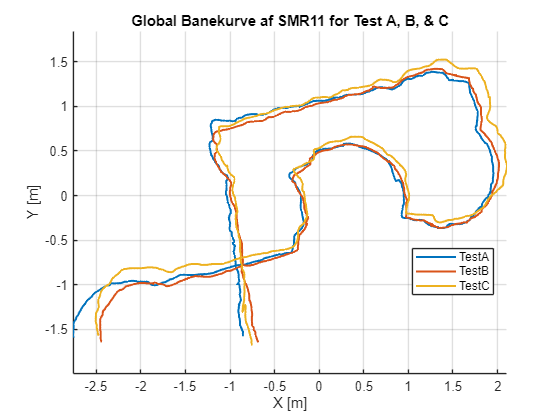

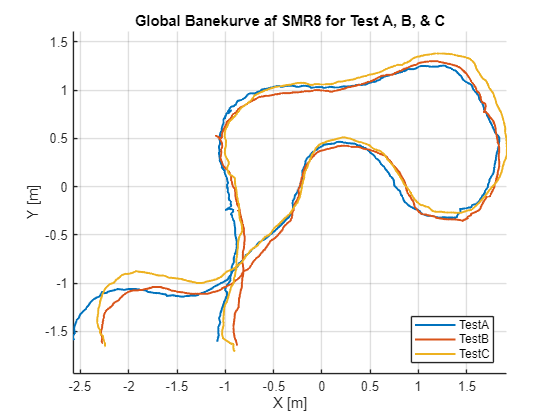

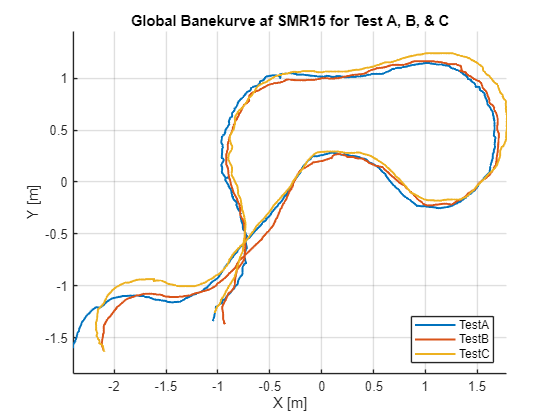

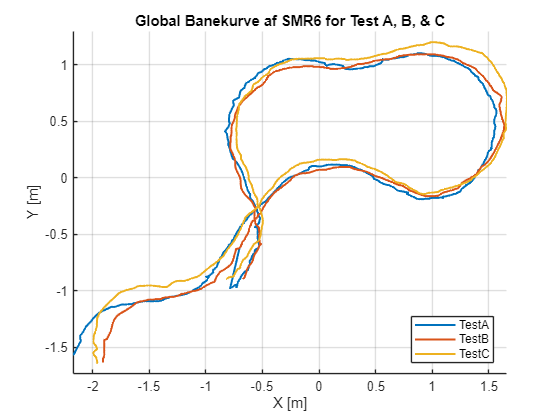




% --- Plot each robot across all tests ---
for r = 1:length(robot_names)
    robot = robot_names{r};
    figure;
    hold on;
    title(['Global Banekurve af ', robot, ' for Test A, B, & C'], 'FontWeight', 'bold');
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal;
    grid on;

    for t = 1:length(fields)
        test = fields{t};

        % Only plot if xg and yg are available
        if isfield(AllTests.(test), robot) && ...
           isfield(AllTests.(test).(robot), 'xg') && ...
           isfield(AllTests.(test).(robot), 'yg')

            xg = AllTests.(test).(robot).xg;
            yg = AllTests.(test).(robot).yg;

            plot(xg, yg, ...
                'DisplayName', test, ...
                'LineWidth', 1.5);
        end
    end

    legend('Location', 'best');
end



% --- Group manually by robot name ---
robots = unique(stats.Robot);
robot_summary = table();

for i = 1:numel(robots)
    r = robots{i};
    sub = stats(strcmp(stats.Robot, r), :);

    % Compute relevant summary stats for the distance error
    robot_summary.Robot(i,1)     = string(r);
    robot_summary.MeanErr(i,1)   = round(mean(sub.MeanErr), 3);
    robot_summary.StdErr(i,1)    = round(mean(sub.StdErr), 3);
    robot_summary.MinErr(i,1)    = round(min(sub.MinErr), 3);
    robot_summary.MaxErr(i,1)    = round(max(sub.MaxErr), 3);
    robot_summary.MedianErr(i,1) = round(mean(sub.MedianErr), 3);
end


% --- Show summary ---
disp(robot_summary)

     Robot     MeanErr    StdErr    MinErr    MaxErr    MedianErr
    _______    _______    ______    ______    ______    _________

    "SMR15"     0.382     0.149      0.01     0.742       0.386  
    "SMR6"      0.666     0.254     0.036     1.155       0.664  
    "SMR8"      0.215     0.071     0.004     0.375       0.218  



## Error

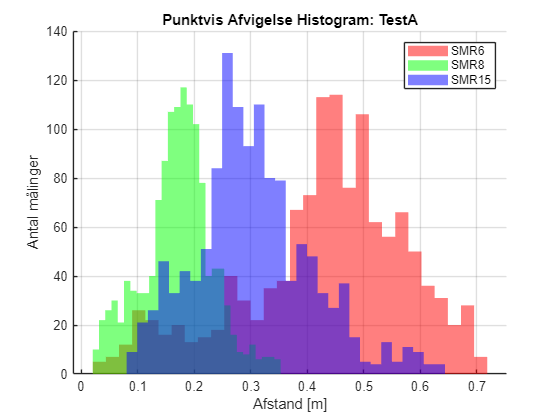

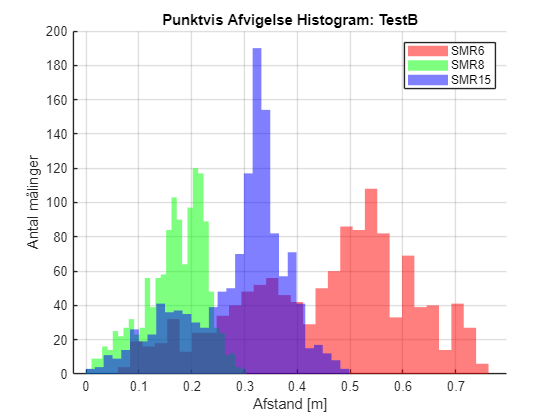

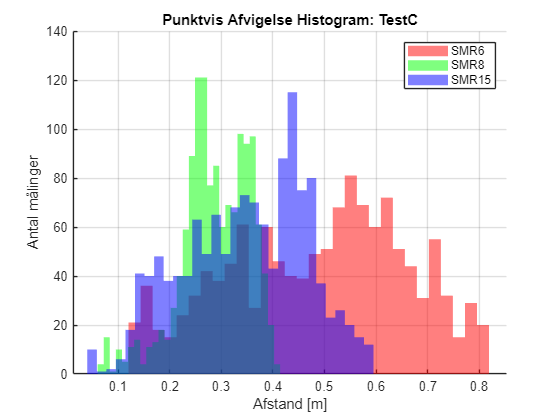

% --- Configuration ---
reference = 'SMR11';
followers = {'SMR6', 'SMR8', 'SMR15'};
colors = containers.Map({'SMR6','SMR8','SMR15'}, {'r','g','b'});

% --- Loop over tests ---
test_names = fieldnames(AllTests);
for t = 1:length(test_names)
    test = test_names{t};

    if ~isfield(AllTests.(test), reference)
        warning('Skipping %s: missing reference.', test);
        continue;
    end

    x_ref = AllTests.(test).(reference).xg;
    y_ref = AllTests.(test).(reference).yg;

    figure('Name', ['Punktvis Afvigelse - ' test], 'Color', 'w');
    hold on;

    % Loop over each follower robot
    for r = 1:length(followers)
        robot = followers{r};

        if ~isfield(AllTests.(test), robot) || ...
           ~isfield(AllTests.(test).(robot), 'xg') || ...
           ~isfield(AllTests.(test).(robot), 'yg')
            warning('Skipping %s in %s: missing global coordinates.', robot, test);
            continue;
        end

        x_f = AllTests.(test).(robot).xg;
        y_f = AllTests.(test).(robot).yg;

        % Clip to common length
        N = min(length(x_f), length(x_ref));
        dx = x_f(1:N) - x_ref(1:N);
        dy = y_f(1:N) - y_ref(1:N);
        pointwise_error = sqrt(dx.^2 + dy.^2);

        % Plot histogram (not normalized)
        histogram(pointwise_error, 30, ...
            'Normalization', 'count', ...
            'DisplayName', robot, ...
            'FaceAlpha', 0.5, ...
            'EdgeColor', 'none', ...
            'FaceColor', colors(robot));
    end

    % Formatting
    title(['Punktvis Afvigelse Histogram: ', test], 'FontWeight', 'bold');
    xlabel('Afstand [m]');
    ylabel('Antal målinger');
    legend('Location', 'northeast');
    grid on;
end

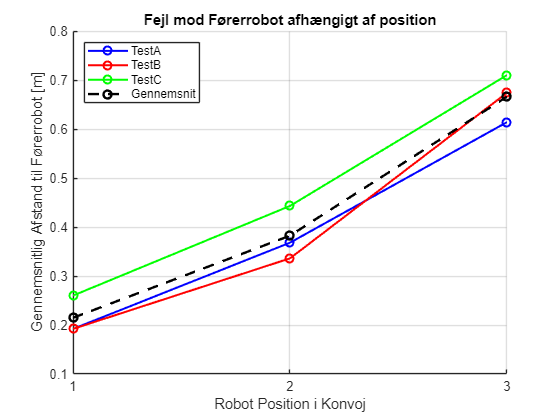




% --- Configuration ---
followers = {'SMR8', 'SMR15', 'SMR6'};  % Convoy order: 1, 2, 3
positions = 1:3;
tests = unique(stats.Test);
color_rgb = {
    [0 0 1],   % TestA - blue
    [1 0 0],  % TestB - red
    [0 1 0]   % TestC - green
};

% --- Initialize matrix ---
mean_matrix = NaN(numel(tests), numel(followers));

% --- Fill matrix with mean errors ---
for i = 1:numel(tests)
    for j = 1:numel(followers)
        row = stats(strcmp(stats.Test, tests{i}) & strcmp(stats.Robot, followers{j}), :);
        if ~isempty(row)
            mean_matrix(i, j) = row.MeanErr;
        end
    end
end

% --- Plot ---
figure;
hold on;
colors = lines(numel(tests));

% Plot each test as a line
for i = 1:numel(tests)
    plot(positions, mean_matrix(i, :), '-o', ...
        'DisplayName', tests{i}, ...
        'Color', color_rgb{i}, ...
        'LineWidth', 1.5);
end

% Add average line across tests
mean_across_tests = mean(mean_matrix, 1, 'omitnan');
plot(positions, mean_across_tests, 'k--o', ...
    'DisplayName', 'Gennemsnit', ...
    'LineWidth', 1.8);

% Axes & labels
xticks(positions);
xticklabels({'1', '2', '3'});
xlabel('Robot Position i Konvoj');
ylabel('Gennemsnitlig Afstand til Førerrobot [m]');
title('Fejl mod Førerrobot afhængigt af position');
legend('Location', 'northwest');
grid on;

## Robot in front

% --- Define follower → leader mapping ---
follower_map = struct( ...
    'SMR8',  'SMR11', ...
    'SMR15', 'SMR8', ...
    'SMR6',  'SMR15' ...
);

followers = fieldnames(follower_map);

% --- Initialize result table ---
stats = table('Size', [0 9], ...
    'VariableTypes', {'string', 'string', 'double', 'double', 'double', 'double', 'double', 'double', 'double'}, ...
    'VariableNames', {'Test', 'Robot', 'MeanErr', 'StdErr', 'MinErr', 'MaxErr', 'MedianErr', 'Q1', 'Q3'});

% --- Loop over tests ---
test_names = fieldnames(AllTests);
for t = 1:length(test_names)
    test = test_names{t};

    % --- Loop over follower robots ---
    for r = 1:length(followers)
        robot = followers{r};
        leader = follower_map.(robot);

        % --- Check data availability ---
        if ~isfield(AllTests.(test), robot) || ...
           ~isfield(AllTests.(test), leader) || ...
           ~isfield(AllTests.(test).(robot), 'xg') || ...
           ~isfield(AllTests.(test).(robot), 'yg') || ...
           ~isfield(AllTests.(test).(leader), 'xg') || ...
           ~isfield(AllTests.(test).(leader), 'yg')
            warning('Skipping %s → %s in %s: missing data.', robot, leader, test);
            continue;
        end

        % --- Get trajectories ---
        x_f = AllTests.(test).(robot).xg;
        y_f = AllTests.(test).(robot).yg;
        x_ref = AllTests.(test).(leader).xg;
        y_ref = AllTests.(test).(leader).yg;

        % --- Interpolate to common time base ---
        t_common = linspace(0, 1, 500);
        x_ref_i = interp1(linspace(0, 1, length(x_ref)), x_ref, t_common, 'linear', 'extrap');
        y_ref_i = interp1(linspace(0, 1, length(y_ref)), y_ref, t_common, 'linear', 'extrap');
        x_f_i   = interp1(linspace(0, 1, length(x_f)),   x_f,   t_common, 'linear', 'extrap');
        y_f_i   = interp1(linspace(0, 1, length(y_f)),   y_f,   t_common, 'linear', 'extrap');

        % --- Distance error ---
        errors = sqrt((x_f_i - x_ref_i).^2 + (y_f_i - y_ref_i).^2);

        % --- Statistics ---
        meanErr   = round(mean(errors), 3);
        stdErr    = round(std(errors), 3);
        minErr    = round(min(errors), 3);
        maxErr    = round(max(errors), 3);
        medianErr = round(median(errors), 3);
        q1        = round(prctile(errors, 25), 3);
        q3        = round(prctile(errors, 75), 3);

        % --- Add row ---
        stats = [stats; {
            test, robot, meanErr, stdErr, minErr, maxErr, medianErr, q1, q3
        }];
    end
end

% --- Show result ---
disp('=== Fejl mellem robot og den forankørende robot ===');

=== Fejl mellem robot og den forankørende robot ===


disp(stats);

     Test       Robot     MeanErr    StdErr    MinErr    MaxErr    MedianErr     Q1       Q3  
    _______    _______    _______    ______    ______    ______    _________    _____    _____

    "TestA"    "SMR8"      0.192     0.081     0.004      0.34         0.2      0.135    0.261
    "TestA"    "SMR15"     0.197     0.085     0.008     0.392       0.195      0.137    0.256
    "TestA"    "SMR6"      0.282     0.115     0.005     0.805       0.299      0.214    0.374
    "TestB"    "SMR8"      0.192      0.07     0.025     0.328       0.192      0.142    0.255
    "TestB"    "SMR15"     0.172      0.07      0.01     0.306       0.182      0.109    0.226
    "TestB"    "SMR6"      0

### Plots

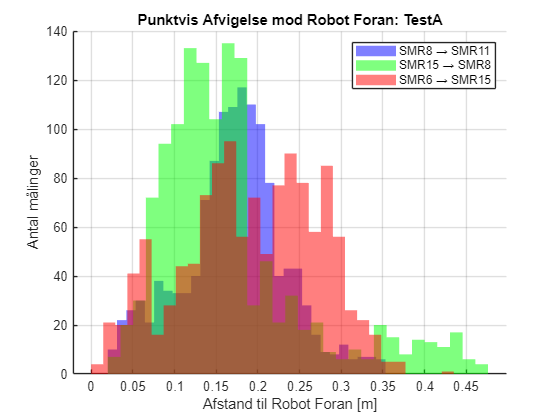

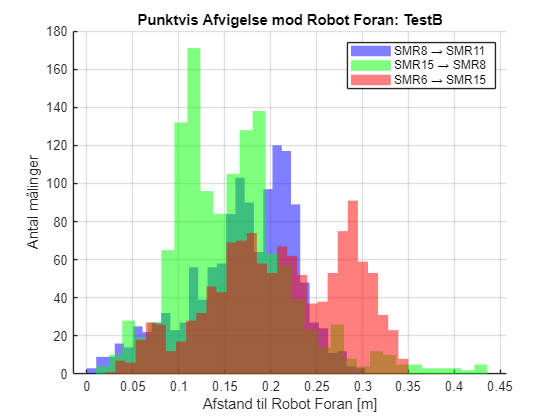

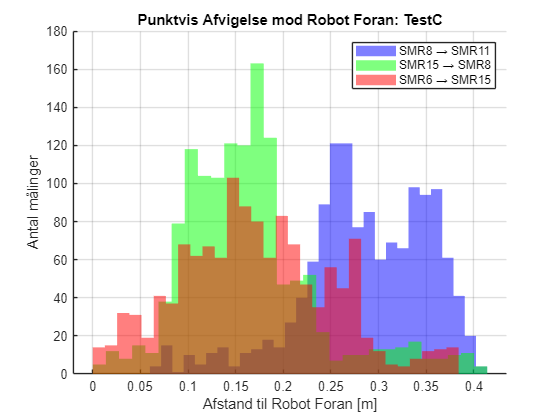

% --- Configuration ---
follower_map = struct('SMR8', 'SMR11', 'SMR15', 'SMR8', 'SMR6', 'SMR15');
followers = {'SMR8', 'SMR15', 'SMR6'};
colors = containers.Map({'SMR8','SMR15','SMR6'}, {'b','g','r'});  % Choose colors per robot

% --- Loop over all test cases ---
test_names = fieldnames(AllTests);
for t = 1:length(test_names)
    test = test_names{t};

    figure('Name', ['Robot → Foran: ' test], 'Color', 'w');
    hold on;
    title(['Punktvis Afvigelse mod Robot Foran: ', test], 'FontWeight', 'bold');

    for r = 1:length(followers)
        robot = followers{r};
        ref = follower_map.(robot);  % Robot directly in front

        % Skip if either robot is missing
        if ~isfield(AllTests.(test), robot) || ~isfield(AllTests.(test), ref) || ...
           ~isfield(AllTests.(test).(robot), 'xg') || ~isfield(AllTests.(test).(robot), 'yg') || ...
           ~isfield(AllTests.(test).(ref), 'xg') || ~isfield(AllTests.(test).(ref), 'yg')
            warning('Skipping %s → %s in %s: data missing.', robot, ref, test);
            continue;
        end

        % Get trajectories
        x_r = AllTests.(test).(robot).xg;
        y_r = AllTests.(test).(robot).yg;
        x_ref = AllTests.(test).(ref).xg;
        y_ref = AllTests.(test).(ref).yg;

        % Align lengths
        N = min([length(x_r), length(y_r), length(x_ref), length(y_ref)]);
        x_r = x_r(1:N); y_r = y_r(1:N);
        x_ref = x_ref(1:N); y_ref = y_ref(1:N);

        % Compute pointwise error
        dx = x_r - x_ref;
        dy = y_r - y_ref;
        dist_error = sqrt(dx.^2 + dy.^2);

        % Plot histogram (count, not relative frequency)
        histogram(dist_error, 30, ...
            'Normalization', 'count', ...
            'DisplayName', sprintf('%s → %s', robot, ref), ...
            'FaceAlpha', 0.5, ...
            'EdgeColor', 'none', ...
            'FaceColor', colors(robot));
    end

    xlabel('Afstand til Robot Foran [m]');
    ylabel('Antal målinger');
    legend('Location', 'northeast');
    grid on;
end

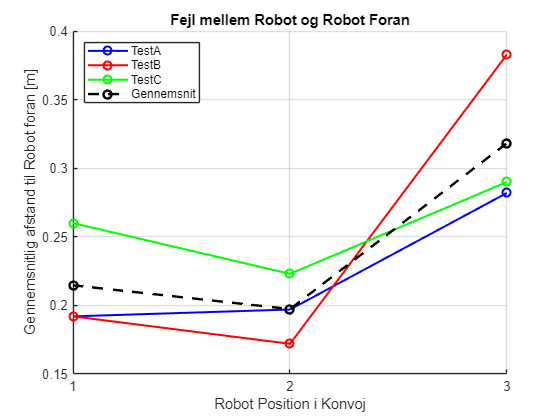


% --- Configuration ---
followers = {'SMR8', 'SMR15', 'SMR6'};  % Convoy order
positions = 1:3;
tests = unique(stats.Test);

color_rgb = {
    [0 0 1],   % TestA - blue
    [1 0 0],  % TestB - red
    [0 1 0]   % TestC - green
};


% --- Initialize matrix ---
mean_front_matrix = NaN(numel(tests), numel(followers));

% --- Fill matrix with mean errors to the robot in front ---
for i = 1:numel(tests)
    for j = 1:numel(followers)
        row = stats(strcmp(stats.Test, tests{i}) & strcmp(stats.Robot, followers{j}), :);
        if ~isempty(row)
            mean_front_matrix(i, j) = row.MeanErr;
        end
    end
end

% --- Plot ---
figure;
hold on;

% Plot each test with its assigned RGB color
for i = 1:numel(tests)
    plot(positions, mean_front_matrix(i, :), '-o', ...
        'DisplayName', tests{i}, ...
        'Color', color_rgb{i}, ...
        'LineWidth', 1.5, ...
        'MarkerSize', 6);
end

% Plot mean line across all tests
mean_across_tests = mean(mean_front_matrix, 1, 'omitnan');
plot(positions, mean_across_tests, 'k--o', ...
    'DisplayName', 'Gennemsnit', ...
    'LineWidth', 1.8, ...
    'MarkerSize', 6);

% Axes & labels
xticks(positions);
xticklabels({'1', '2', '3'});
xlabel('Robot Position i Konvoj');
ylabel('Gennemsnitlig afstand til Robot foran [m]');
title('Fejl mellem Robot og Robot Foran');
legend('Location', 'northwest');
grid on;